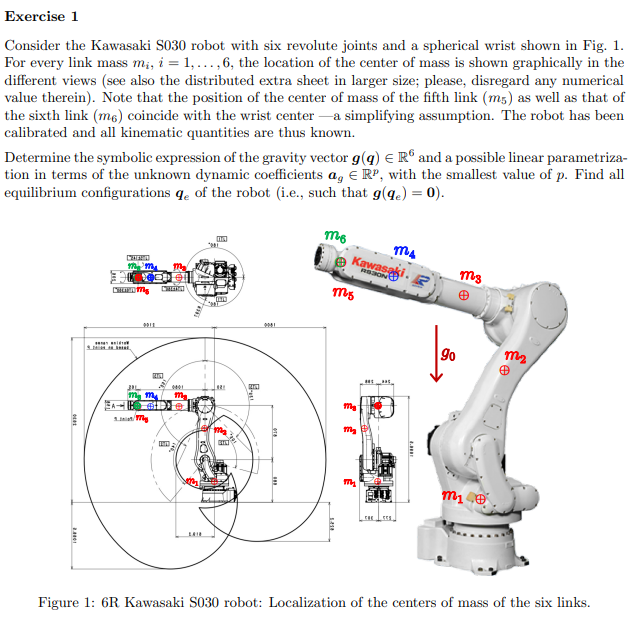

syms q1 q2 q3 q4 q5 q6 l_1 l_2 l_3 l_4 l_5 l_6 g0 a_1 a_2 real
syms m_1 m_2 m_3 m_4 m_5 m_6 d_1 d_2 d_3 d_4 d_5 d_6 real

U1 = 0

U1 = 0

U2 = m_2*g0*(l_1+d_2*sin(q2))

$$U2 = g_{0}\,m_{2}\,\left(l_{1}+d_{2}\,\sin\left(q_{2}\right)\right)$$

U3 = m_3*g0*(l_1+l_2*sin(q2)+d_3*sin(q2+q3))

$$U3 = g_{0}\,m_{3}\,\left(l_{1}+d_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\right)$$

U4 = m_4*g0*(l_1+l_2*sin(q2)+d_4*sin(q2+q3))

$$U4 = g_{0}\,m_{4}\,\left(l_{1}+d_{4}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\right)$$

U5 = (m_5+m_6)*g0*(l_1+l_2*sin(q2)+l_5*sin(q2+q3))

$$U5 = g_{0}\,\left(m_{5}+m_{6}\right)\,\left(l_{1}+l_{5}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\right)$$


U = simplify([U1+U2+U3+U4+U5])

$$U = g_{0}\,m_{3}\,\left(l_{1}+d_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\right)+g_{0}\,m_{4}\,\left(l_{1}+d_{4}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\right)+g_{0}\,m_{2}\,\left(l_{1}+d_{2}\,\sin\left(q_{2}\right)\right)+g_{0}\,\left(m_{5}+m_{6}\right)\,\left(l_{1}+l_{5}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\right)$$

U_subs = g0*(a_1*(l_2*sin(q2)+l_1)+a_2*(d_3*sin(q3)+d_4*sin(q3+q2)+l_5*sin(q2+q3)))

$$U\_subs = g_{0}\,\left(a_{1}\,\left(l_{1}+l_{2}\,\sin\left(q_{2}\right)\right)+a_{2}\,\left(d_{4}\,\sin\left(q_{2}+q_{3}\right)+l_{5}\,\sin\left(q_{2}+q_{3}\right)+d_{3}\,\sin\left(q_{3}\right)\right)\right)$$

g_q = simplify([diff(U_subs,q1); diff(U_subs,q2); diff(U_subs,q3); diff(U_subs,q4); diff(U_subs,q5); diff(U_subs,q6);], Steps=100)

$$g\_q = \left(\begin{array}{c} 0\\ a_{2}\,g_{0}\,\left(d_{4}\,\cos\left(q_{2}+q_{3}\right)+l_{5}\,\cos\left(q_{2}+q_{3}\right)\right)+a_{1}\,g_{0}\,l_{2}\,\cos\left(q_{2}\right)\\ a_{2}\,g_{0}\,\left(d_{4}\,\cos\left(q_{2}+q_{3}\right)+l_{5}\,\cos\left(q_{2}+q_{3}\right)+d_{3}\,\cos\left(q_{3}\right)\right)\\ 0\\ 0\\ 0 \end{array}\right)$$

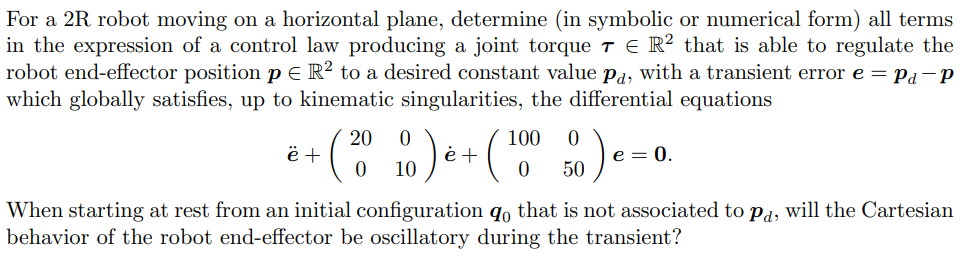

syms q1 q2 q_dot_1 q_dot_2 m_1 m_2 d_1 d_2 L_2 L_1 I_1 I_2 real

x1 = d_1*cos(q1);
y1 = d_1*sin(q1);
vx1 = diff(x1,q1)*q_dot_1+diff(x1,q2)*q_dot_2

$$vx1 = -d_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)$$

vy1 = diff(y1,q1)*q_dot_1+diff(y1,q2)*q_dot_2

$$vy1 = d_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)$$

T1 = 0.5*m_1*[vx1 vy1]*[vx1; vy1;]+0.5*I_1*[0 0 q_dot_1]*[0; 0; q_dot_1;]

$$T1 = \frac{m_{1}\,{d_{1}}^{2}\,{{\dot{q}}_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{m_{1}\,{d_{1}}^{2}\,{{\dot{q}}_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{2}+\frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$


x2 = L_1*cos(q1)+d_2*cos(q1+q2);
y2 = L_1*sin(q1)+d_2*sin(q1+q2);
vx2 = diff(x2,q1)*q_dot_1+diff(x2,q2)*q_dot_2

$$vx2 = -{\dot{q}}_{1}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+L_{1}\,\sin\left(q_{1}\right)\right)-d_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)$$

vy2 = diff(y2,q1)*q_dot_1+diff(y2,q2)*q_dot_2

$$vy2 = {\dot{q}}_{1}\,\left(d_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{1}\,\cos\left(q_{1}\right)\right)+d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)$$

T2 = 0.5*m_2*[vx2 vy2]*[vx2; vy2;]+0.5*I_2*[0 0 q_dot_1+q_dot_2]*[0; 0; q_dot_1+q_dot_2;]

$$T2 = \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(d_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{1}\,\cos\left(q_{1}\right)\right)+d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+L_{1}\,\sin\left(q_{1}\right)\right)+d_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\right)}^{2}}{2}$$

T = T1+T2

$$T = \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(d_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{1}\,\cos\left(q_{1}\right)\right)+d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+L_{1}\,\sin\left(q_{1}\right)\right)+d_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\right)}^{2}}{2}+\frac{{d_{1}}^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{{d_{1}}^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);

M = simplify([M11, M12; M21, M22;])

$$M = \left(\begin{array}{cc} m_{2}\,{L_{1}}^{2}+2\,m_{2}\,\cos\left(q_{2}\right)\,L_{1}\,d_{2}+m_{1}\,{d_{1}}^{2}+m_{2}\,{d_{2}}^{2}+I_{1}+I_{2} & m_{2}\,{d_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(q_{2}\right)\,d_{2}+I_{2}\\ m_{2}\,{d_{2}}^{2}+L_{1}\,m_{2}\,\cos\left(q_{2}\right)\,d_{2}+I_{2} & m_{2}\,{d_{2}}^{2}+I_{2} \end{array}\right)$$


% Coriolis and Centrifugal terms
q  = [q1; q2;];
dq = [q_dot_1; q_dot_2;];
C = sym(zeros(2,2));

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} -L_{1}\,d_{2}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & -L_{1}\,d_{2}\,m_{2}\,\sin\left(q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ L_{1}\,d_{2}\,m_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -L_{1}\,d_{2}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ L_{1}\,d_{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}\right) \end{array}\right)$$